# **HW10 [ALL CORRECT]**

# Q1

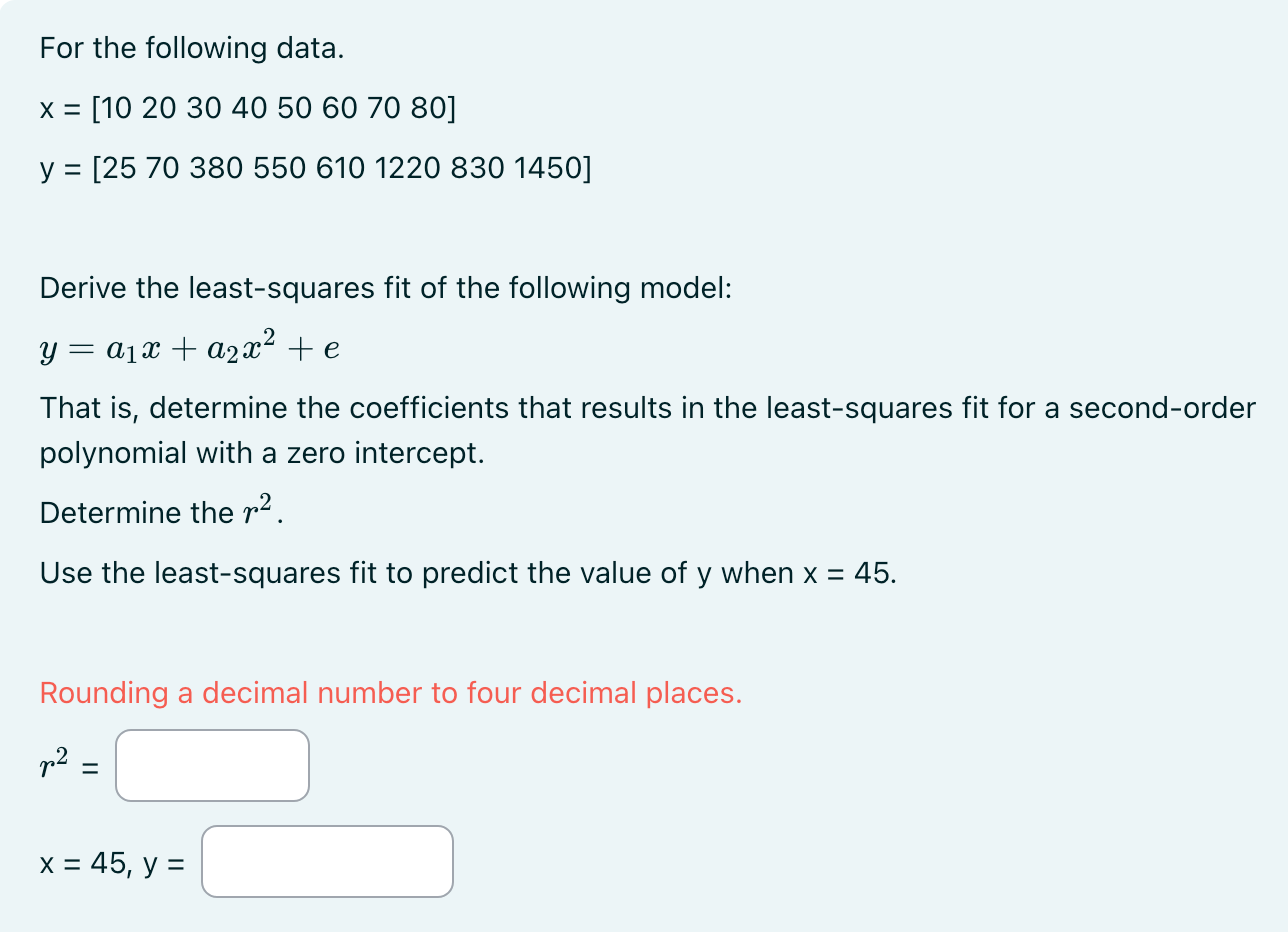

% CORRECT

x = [10 20 30  40  50  60   70  80]';
y = [25 70 380 550 610 1220 830 1450]';

% GENERAL APPROACH
% y = Za + e
Z = [x x.^2] % no ones() because there's no a_0 terms in the given expression

Z =           10         100
          20         400
          30         900
          40        1600
          50        2500
          60        3600
          70        4900
          80        6400


a = (Z'*Z) \ (Z'*y)

a =     7.7710
    0.1191


xpred = 45

xpred = 45

ypred = (a(1)*xpred) + (a(2)*xpred.^2)

ypred = 590.8228

ytrue = (a(1).*x) + (a(2).*x.^2)

ytrue = 1.0e+03 *

    0.0896
    0.2031
    0.3403
    0.5014
    0.6862
    0.8949
    1.1274
    1.3838


st = sum((y - mean(y)) .^ 2)

st = 1.8083e+06

sr = sum((y - ytrue) .^ 2)

sr = 2.3016e+05

r2 = 1 - (sr/st)

r2 = 0.8727

# Q2 (similar to HW09)

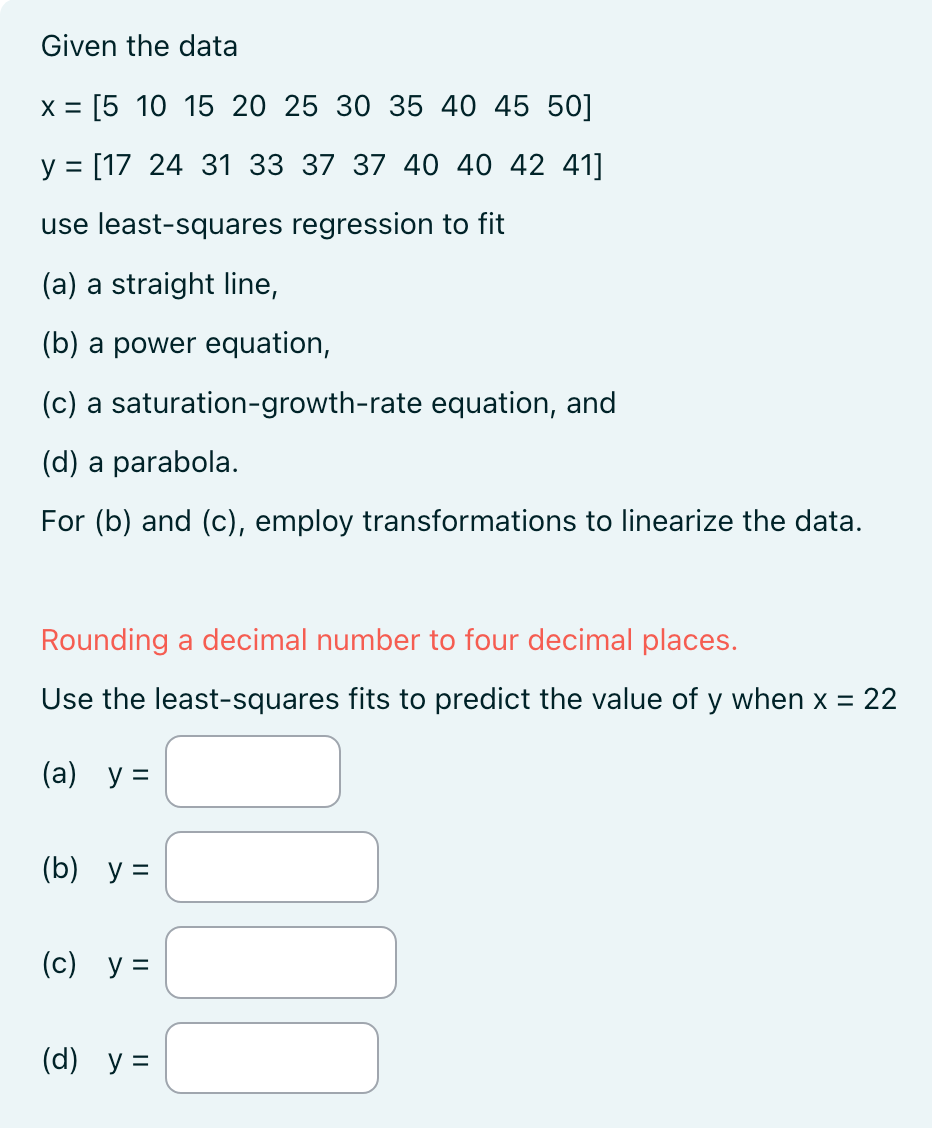

% dataset
x = [5  10  15  20  25  30  35  40  45  50];
y = [17  24  31  33  37  37  40  40  42  41];
xplot = linspace(min(x), max(x), 100)

xplot =     5.0000    5.4545    5.9091    6.3636    6.8182    7.2727    7.7273    8.1818    8.6364    9.0909    9.5455   10.0000   10.4545   10.9091   11.3636   11.8182   12.2727   12.7273   13.1818   13.6364   14.0909   14.5455   15.0000   15.4545   15.9091   16.3636   16.8182   17.2727   17.7273   18.1818   18.6364   19.0909   19.5455   20.0000   20.4545   20.9091   21.3636   21.8182   22.2727   22.7273   23.1818   23.6364   24.0909   24.5455   25.0000   25.4545   25.9091   26.3636   26.8182   27.2727


xtest = 22

xtest = 22


% Linear (straight line) fit
Lp1 = polyfit(x, y, 1)

Lp1 =     0.4945   20.6000


Lyy1 = polyval(Lp1, x)

Lyy1 =    23.0727   25.5455   28.0182   30.4909   32.9636   35.4364   37.9091   40.3818   42.8545   45.3273


Lytest1 = polyval(Lp1, xtest)

Lytest1 = 31.4800


% Power equation linearization [can't use polyfit/polyval; no degrees]
Pnew_x = log10(x)

Pnew_x =     0.6990    1.0000    1.1761    1.3010    1.3979    1.4771    1.5441    1.6021    1.6532    1.6990


Pnew_y = log10(y)

Pnew_y =     1.2304    1.3802    1.4914    1.5185    1.5682    1.5682    1.6021    1.6021    1.6232    1.6128


Pa =     0.3851    0.9980


[Pa, ~] = linregr(Pnew_x, Pnew_y)

Pslp = Pa(1)

Pslp = 0.3851

Pint = Pa(2)

Pint = 0.9980

Palpha = 10^Pint

Palpha = 9.9529

Pbeta = Pslp

Pbeta = 0.3851

Pytest = Palpha .* (xtest .^ Pbeta)

Pytest = 32.7255

% Pyplot = Palpha .* (xplot .^ Pbeta)
% plot(x, y, 'o', xplot, Pyplot)

% Saturation growth rate linearization [can't use polyfit/polyval; no degrees]
Snew_x = 1 ./ x

Snew_x =     0.2000    0.1000    0.0667    0.0500    0.0400    0.0333    0.0286    0.0250    0.0222    0.0200


Snew_y = 1 ./ y

Snew_y =     0.0588    0.0417    0.0323    0.0303    0.0270    0.0270    0.0250    0.0250    0.0238    0.0244


Sa =     0.1975    0.0200


[Sa, ~] = linregr(Snew_x, Snew_y)

Sslp = Sa(1)

Sslp = 0.1975

Sint = Sa(2)

Sint = 0.0200

Salpha = 1 / Sint

Salpha = 50.0921

Sbeta = Salpha * Sslp

Sbeta = 9.8914

% Syplot = Salpha .* (xplot ./ (Sbeta + xplot))
Sytest = Salpha .* (xtest ./ (Sbeta + xtest))

Sytest = 34.5556

% plot(x, y, 'o', xplot, Syplot, '-')

% parabola (Quadratic) fit
Qp2 = polyfit(x, y, 2)

Qp2 =    -0.0161    1.3779   11.7667


Qyy2 = polyval(Qp2, x)

Qyy2 =    18.2545   23.9394   28.8212   32.9000   36.1758   38.6485   40.3182   41.1848   41.2485   40.5091


Qytest2 = polyval(Qp2, xtest)

Qytest2 = 34.3067

# Q3

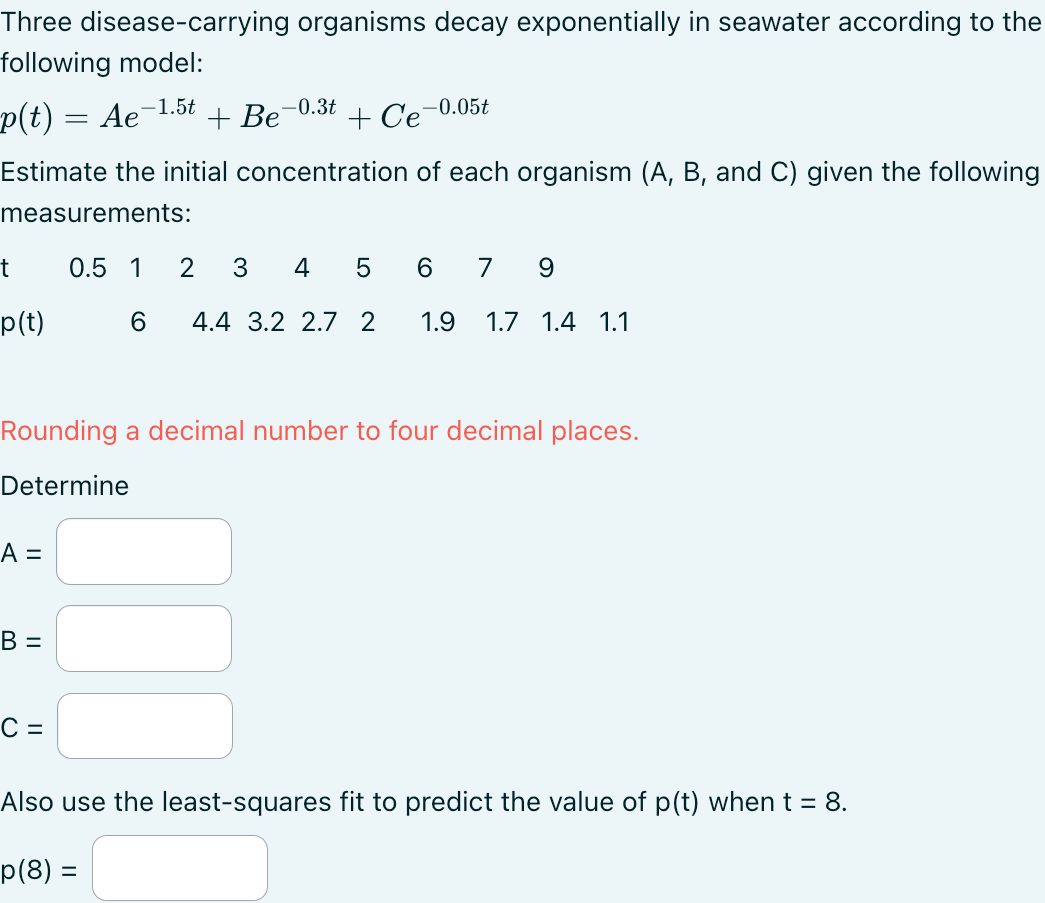

% CORRECT

format short

t 	= [0.5   1     2     3      4      5      6      7      9]';
p 	= [6      4.4  3.2  2.7   2      1.9    1.7   1.4   1.1]';
ttest = 8

ttest = 8


Z = [exp(-1.5*t) exp(-0.3*t) exp(-0.05*t)]

Z =     0.4724    0.8607    0.9753
    0.2231    0.7408    0.9512
    0.0498    0.5488    0.9048
    0.0111    0.4066    0.8607
    0.0025    0.3012    0.8187
    0.0006    0.2231    0.7788
    0.0001    0.1653    0.7408
    0.0000    0.1225    0.7047
    0.0000    0.0672    0.6376


a = (Z' * Z) \ (Z' * p)

a =     4.1375
    2.8959
    1.5349


ypred = a(1)*exp(-1.5*ttest) + a(2)*exp(-0.3*ttest) + a(3)*exp(-0.05*ttest)

ypred = 1.2916

# Q4

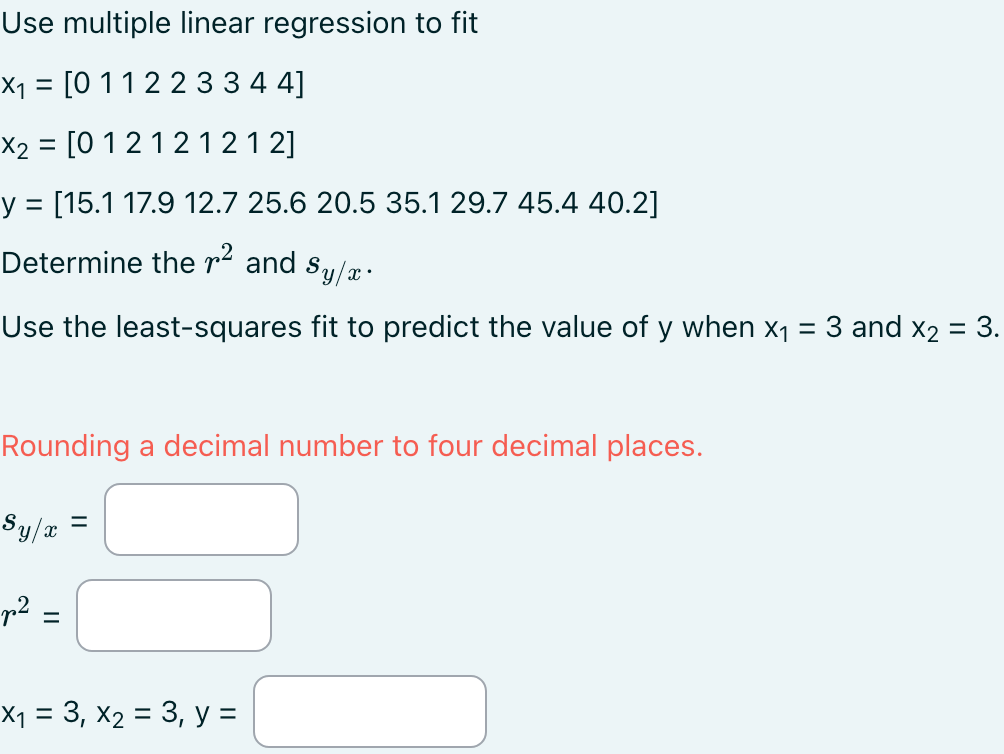

x1 = [0 1 1 2 2 3 3 4 4]';
x2 = [0 1 2 1 2 1 2 1 2]';
y = [15.1 17.9 12.7 25.6 20.5 35.1 29.7 45.4 40.2]';
Z = [ones(size(y)), x1, x2]

Z =      1     0     0
     1     1     1
     1     1     2
     1     2     1
     1     2     2
     1     3     1
     1     3     2
     1     4     1
     1     4     2


a = (Z' * Z) \ (Z' * y)

a =    14.4609
    9.0252
   -5.7043


sr = sum((y - (Z*a)).^2)

sr = 4.7397

st = sum((y - mean(y)).^2)

st = 1.0587e+03

r2 = 1 - (sr/st)

r2 = 0.9955

syx = sqrt(sr/(length(y)-3))

syx = 0.8888


x1test = 3;
x2test = 3;

ypred = a(1) + (a(2) * x1test) + (a(3) * x2test)

ypred = 24.4235

# Q5

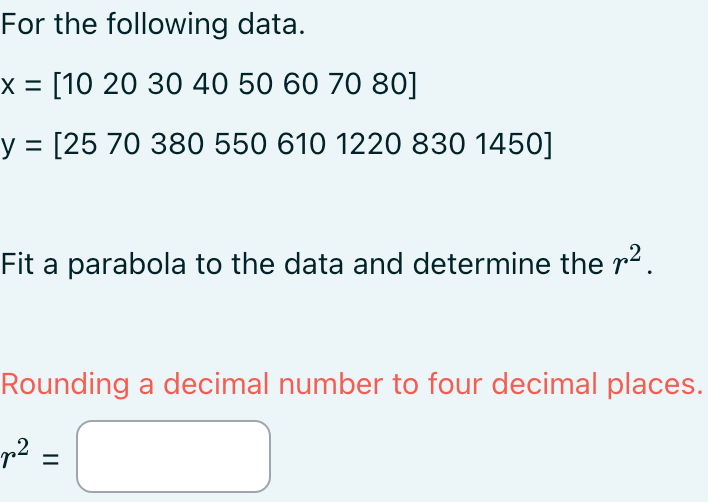

x = [10 20 30 40 50 60 70 80];
y = [25 70 380 550 610 1220 830 1450];
p = polyfit(x, y, 2)

p =     0.0372   16.1220 -178.4821


sr = sum((y - polyval(p, x)) .^ 2)

sr = 2.1379e+05

st = sum((y - mean(y)) .^2)

st = 1.8083e+06

r2 = 1 - (sr/st)

r2 = 0.8818

### `linregr` function

function [a, r2] = linregr(x,y)
    % linregr: linear regression curve fitting
    % [a, r2] = linregr(x,y): Least squares fit of straight
    % line to data by solving the normal equations
    % input:
    % x = independent variable
    % y = dependent variable
    % output:
    % a = vector of slope, a(1), and intercept, a(2)
    % r2 = coefficient of determination
    n = length(x);
    if length(y)~=n, error('x and y must be same length'); end
    x = x(:); y = y(:); % convert to column vectors
    sx = sum(x); sy = sum(y);
    sx2 = sum(x.*x); sxy = sum(x.*y); sy2 = sum(y.*y);
    a(1) = (n*sxy-sx*sy)/(n*sx2-sx^2);
    a(2) = sy/n-a(1)*sx/n;
    r2 = ((n*sxy-sx*sy)/sqrt(n*sx2-sx^2)/sqrt(n*sy2-sy^2))^2;
    % create plot of data and best fit line
    xp = linspace(min(x),max(x),2);
    yp = a(1)*xp+a(2);
    plot(x,y,'o',xp,yp)
    grid on
end